PROJECT 1: correlation and power spercrum density

read an arbitrary signal :

[audio , fs] = audioread('data.wav');
% sound(data , fs)

frequency representation of data :

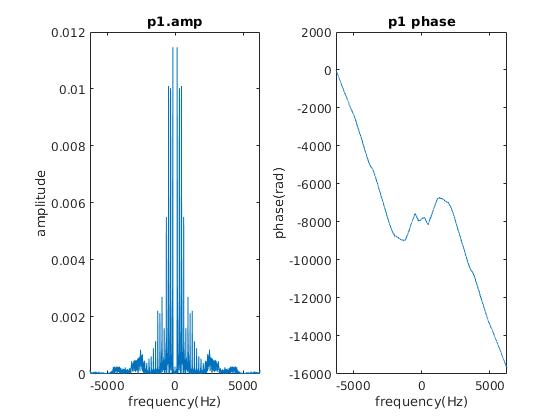

[f_audio,frequency_audio] = ft(audio , fs);
figure
subplot(1,2,1);
plot(frequency_audio , abs(f_audio))
title('p1.amp')
xlabel('frequency(Hz)')
ylabel('amplitude')
subplot(1,2,2);
plot(frequency_audio , phase(f_audio))
title('p1 phase')
xlabel('frequency(Hz)')
ylabel('phase(rad)')

what does the negative part of frequency axis represent by your intuition ???

## cross corr and auto corr:

using main formula:

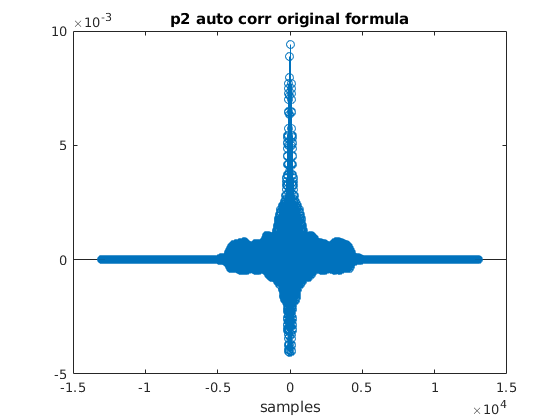

figure
corr_audio = corr_sigma(audio , audio,fs);
corr_lim = (max(size(corr_audio))-1)/2;
x = [-corr_lim :1:corr_lim];
stem(x , corr_audio);
title('p2 auto corr original formula')
xlabel('samples')

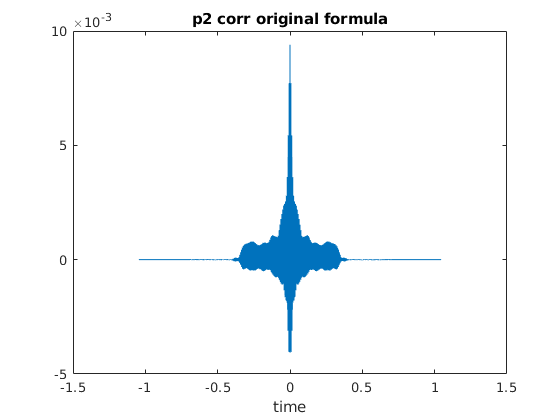

x = [-corr_lim :1:corr_lim]./fs;
plot(x , corr_audio);
title('p2 corr original formula')
xlabel('time')

using convolution base computations:

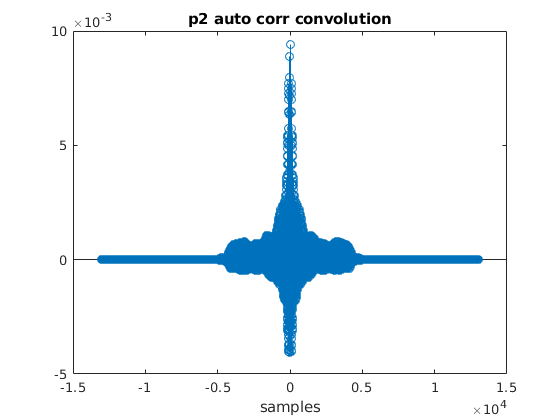

figure
auto_corr = corr_conv( audio, audio,fs);
corr_lim = (max(size(auto_corr))-1)/2;
x = [-corr_lim :1:corr_lim];
stem(x , auto_corr);
title('p2 auto corr convolution')
xlabel('samples')

power of signal and auto corr:

power = sum(audio .^2)*fs;
corr_peak = auto_corr(corr_lim +1);
corr_peak = corr_audio(corr_lim + 1);

**note the hermition symmetry of auto correlation 

note that auto corr function has negetive values , what could this mean by your intuition ?

### auto corr of periodic signals:

% x = linspace(-10 , 10 , 1000);
% fs = 1000/20;
% data = sin(2*x + pi*rand()) + sin(7*x + pi*rand());
% stem(data)
% title('random phase cosine signal')
% xlabel('sample')
% ylabel('amplitude')
% 
% corr = corr_sigma(data , data,fs);
% corr_lim = (max(size(corr))-1)/2;
% x = [-corr_lim :1:corr_lim];
% stem(x, corr)
% title('periodic corr of periodic signals')
% xlabel('sample')
% ylabel('amplitude')

***corr on linear combination of signal*** :

% x =ones(101,1);
% middle = ones(1,1);
% pad = zeros(1000,1);
% data = cat(1,pad ,x ,middle, flip(x),pad);
% lim = (max(size(data))-1)/2;
% x = [-lim :1:lim];
% stem(x,data)
% title('signal')
% xlabel('sample')
% ylabel('amplitude')

% corr = corr_sigma(data , data,1);
% lim = (max(size(corr))-1)/2;
% x = [-lim :1:lim];
% stem(x,corr)
% title('auto corr')
% xlabel('sample')
% ylabel('amplitude')

## comparison of power spectrum density

fs = 300

fs = 300

ts = 1/fs

ts = 0.0033

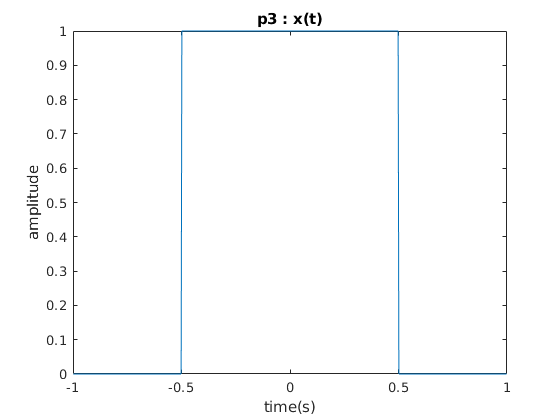

x = ones(fs,1);
pad = zeros(fs/2,1);
input = cat(1,pad , x, pad);
lim = (max(size(input))-1)/2;
x = [-lim :1:lim];
plot(x.*ts, input)
title("p3 : x(t)")
xlabel('time(s)')
ylabel('amplitude')

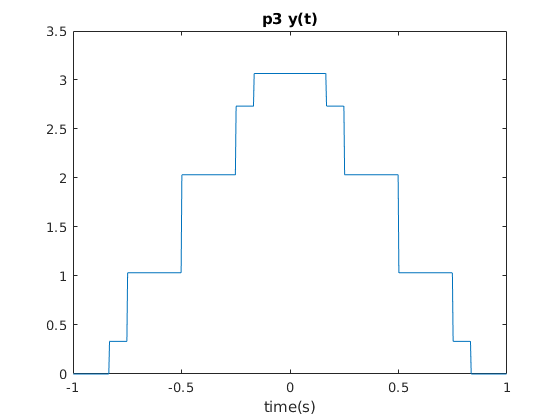

shifts = [-fs/3,-fs/4,fs/4 , fs/3];
scales = [1/3,0.7,0.7 ,1/3];

distorted_data = shift_scale(input , shifts , scales);

lim = (max(size(distorted_data))-1)/2;
x_t = [-lim :1:lim];
plot(x_t.*ts , distorted_data)
title('p3 y(t)')
xlabel('time(s)')

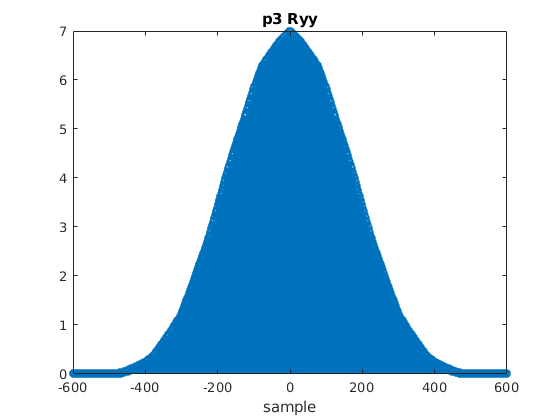


corr = corr_sigma( distorted_data, distorted_data,fs);
lim = (max(size(corr))-1)/2;
x_t = [-lim :1:lim];
stem(x_t , corr)
title('p3 Ryy')
xlabel('sample')

[f,frequency] = ft(input , fs);
% plot(frequency , abs(f))
% title('siganl in frequency domain')
% xlabel('frequency(Hz)')
% ylabel('amplitude')

calculate power from time domain signal:

energy_time = sum(input.^2.*ts)

energy_time = 1.0000

calculate signal power using auto correlation of signal:

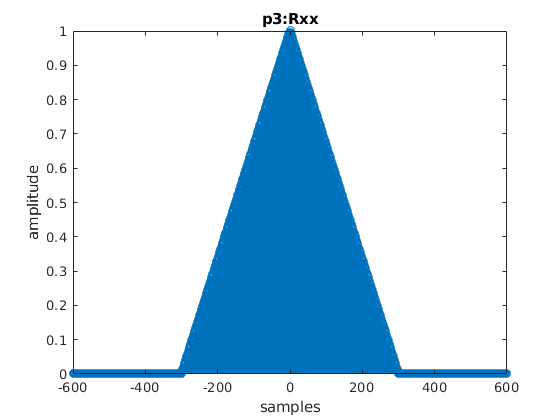

corr_input = corr_sigma(input , input,fs);
lim = (max(size(corr_input))-1)/2;
x = [-lim :1:lim];
stem(x,corr_input)
title('p3:Rxx')
xlabel('samples')
ylabel('amplitude')


energy_corr = max(corr_input)

energy_corr = 1

calculaate power using power spcrtal density:

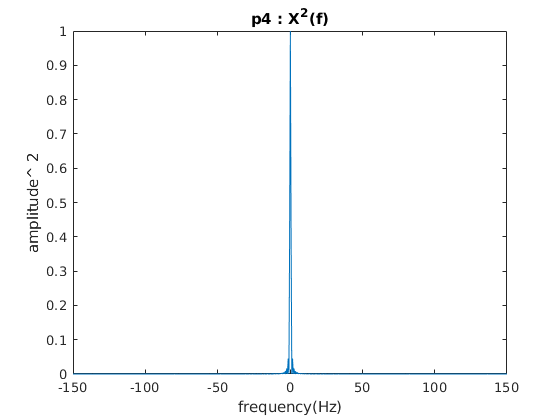

f_square = abs(f).^2;
[psd_input,freq] = ft(corr_input,fs);

plot(frequency , f_square);
title('p4 : X^2(f)')
xlabel('frequency(Hz)')
ylabel('amplitude\^ 2')

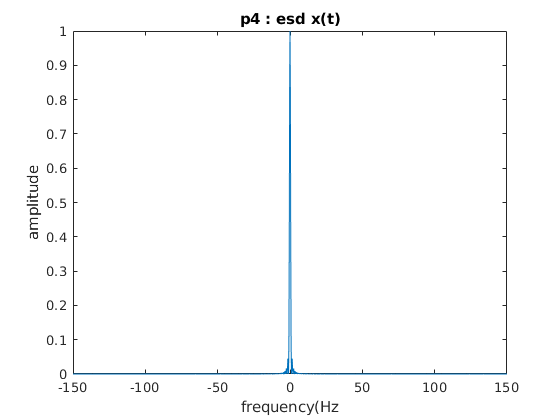


plot(freq , abs(psd_input));
title('p4 : esd x(t)')
xlabel('frequency(Hz')
ylabel('amplitude')


energy_esd_fft_corr =  sum(abs(psd_input).*1/4)

energy_esd_fft_corr = 0.9992

energy_esd_fsquare = sum(f_square.*1/2)

energy_esd_fsquare = 1.0000

## correlation and psd through linear time invarient filters

let's try a simple filter :

fs = 300

fs = 300

ts = 1/fs

ts = 0.0033

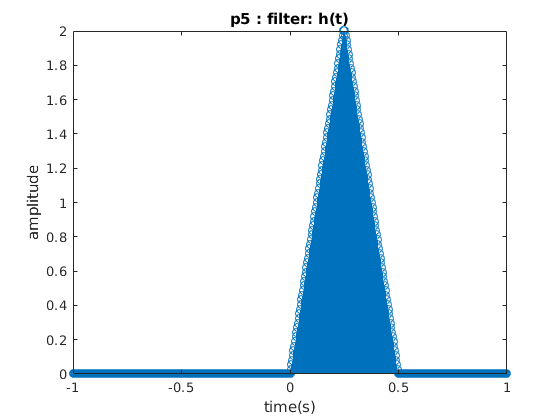

x = linspace(0,2,fs/4);
x = x.';    
pad1 = zeros(fs,1);
pad2 = zeros(fs/2,1);
filter = cat(1,pad1 , x , flip(x), pad2);
lim = (max(size(filter))-1)/2;
x = [-lim :1:lim];
stem(x.*ts, filter)
title("p5 : filter: h(t)")
xlabel('time(s)')
ylabel('amplitude')

filter in frequency domain:

[f,frequency] = ft(filter , fs);
% plot(frequency , abs(f))
% title('siganl in frequency domain')
% xlabel('frequency(Hz)')
% ylabel('amplitude')

auto correlation of filter:

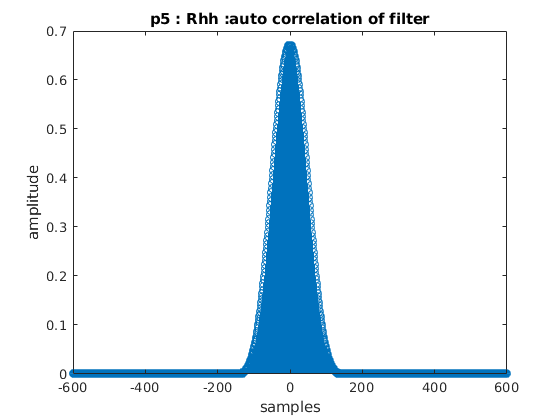

corr_filter = corr_sigma(filter , filter,fs);
lim = (max(size(corr_filter))-1)/2;
x = [-lim :1:lim];  
stem(x,corr_filter)
title('p5 : Rhh :auto correlation of filter')
xlabel('samples')
    ylabel('amplitude')

psd of filter :

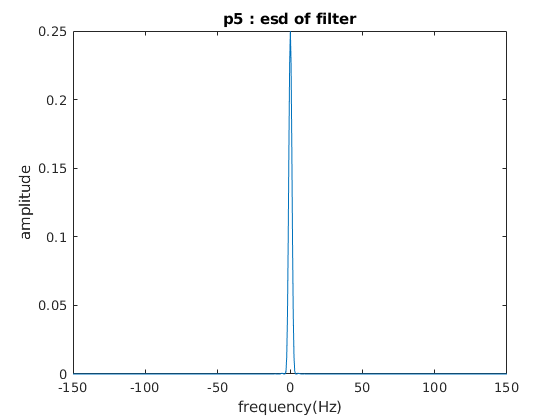

psd_filter = ft(corr_filter , fs);
plot(frequency , abs(f).^2)
title('p5 : esd of filter')
xlabel('frequency(Hz)')
ylabel('amplitude')

filter the  input:

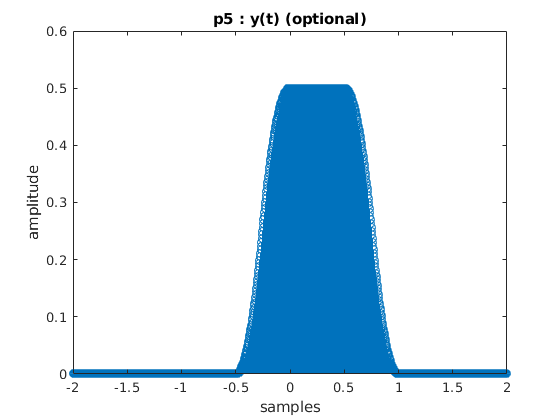

out = conv(input , filter).*ts;
lim = (max(size(out))-1)/2;
x = [-lim :1:lim];
stem(x.*ts,out)
title('p5 : y(t) (optional)')
xlabel('samples')
ylabel('amplitude')

fourier of output :

[f_out,frequency_out] = ft(out , fs);
% plot(frequency_out , abs(f_out))
% title('output in frequency domain')
% xlabel('frequency(Hz)')
% ylabel('amplitude')

correlation of output :

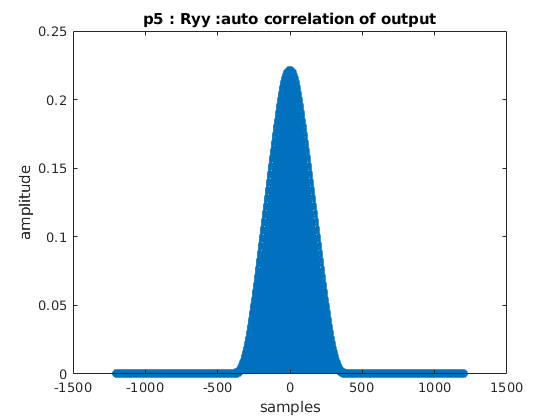

corr_out = corr_sigma(out, out,fs);
lim = (max(size(corr_out))-1)/2;
x = [-lim :1:lim];
stem(x,corr_out)
title('p5 : Ryy :auto correlation of output')
xlabel('samples')
ylabel('amplitude')

psd of output:

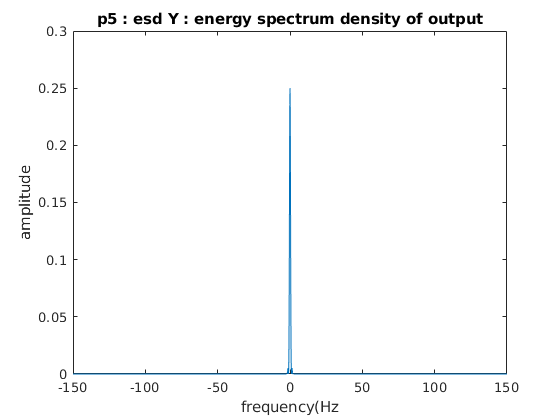

[psd_out,freq] = ft(corr_out,fs);
plot(freq , abs(psd_out));
title('p5 : esd Y : energy spectrum density of output')
xlabel('frequency(Hz')
ylabel('amplitude')

## sanity check:

- Ry(T) = Rx(T) * h(T) * conj(h(-T))

- Gy(f) = Gx(f) |H(f)|^2

1. 

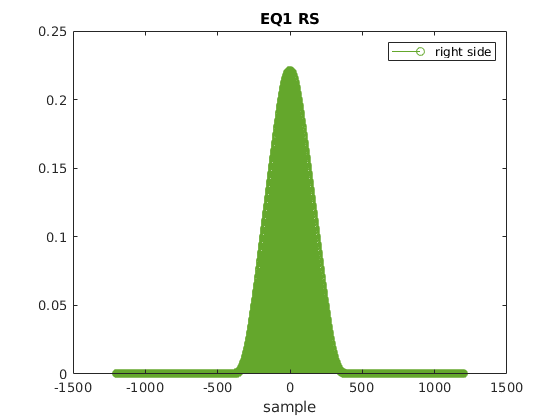


right_side = conv(((conv(filter , conj(flip(filter)))).*ts),corr_input).*ts;
left_side = corr_out;
lim = (max(size(left_side))-1)/2;
x = [-lim :1:lim];
figure;
stem(x , right_side ,'Color',[rand() , rand() , rand()] , 'DisplayName','right side');
title('EQ1 RS')
xlabel('sample')
legend;

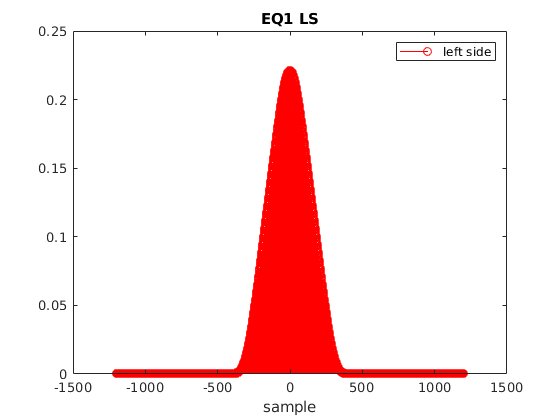

% hold on;
stem(x, left_side , 'Color','red','DisplayName','left side');
title('EQ1 LS')
xlabel('sample')
legend;

% hold off;


2.

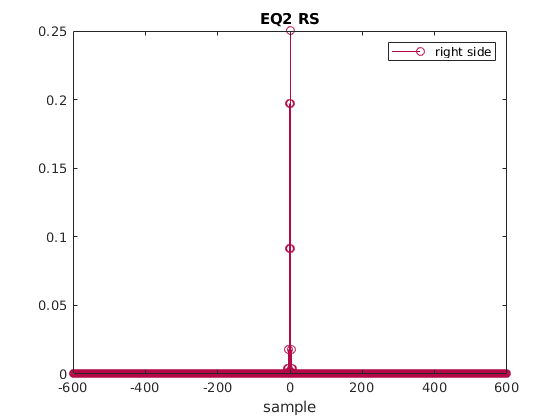

left_side = downsample(psd_out,2);
right_side = psd_input .* psd_filter;
lim = (max(size(right_side))-1)/2;
x = [-lim :1:lim];
figure;
stem(x , abs(right_side) ,'Color',[rand() , rand() , rand()], 'DisplayName','right side');
title('EQ2 RS')
xlabel('sample')
legend;

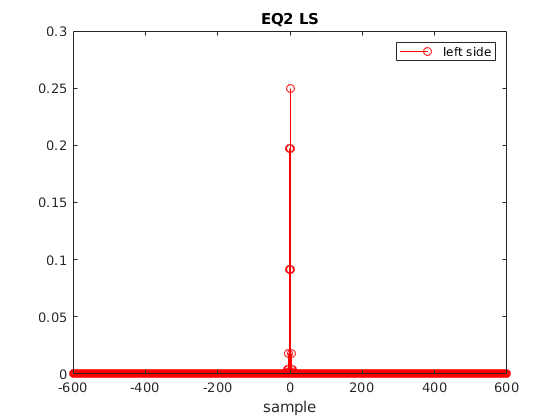

% hold on;
lim = (max(size(left_side))-1)/2;
x = [-lim :1:lim];
stem(x, abs(left_side) , 'Color','red','DisplayName','left side');
title('EQ2 LS')
xlabel('sample')
legend;

% hold off;
